syms f(x)
a = 0

a = 0

b = 1.1

b = 1.1000

f(x) = a*x-b*x^2

$$f(x) = -\frac{11\,x^{2}}{10}$$

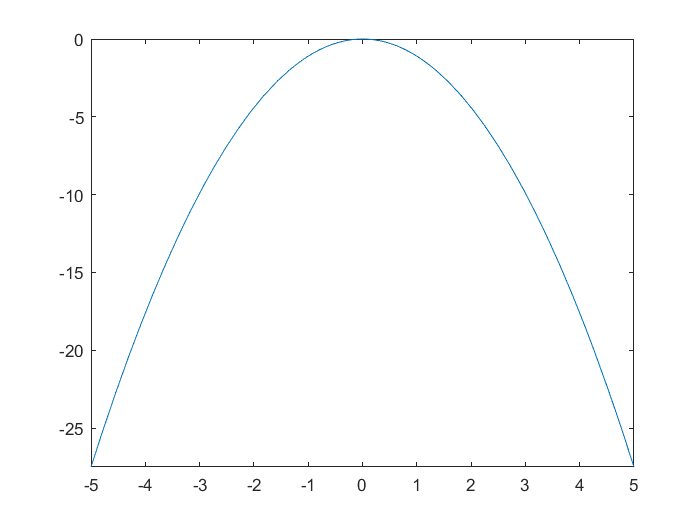


fplot(f(x),[-5,5])

syms f(x)
a = 1

a = 1

b = 1

b = 1

f(x) = -a*sin(x)-2*b*sin(2*x)

$$f(x) = -2\,\sin\left(2\,x\right)-\sin\left(x\right)$$

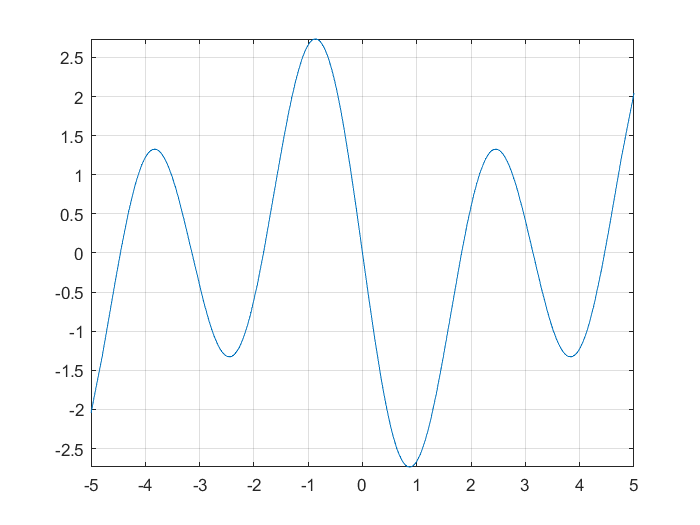


fplot(f(x))
grid on

# HW5 answer key

syms f(x)
f(x) = 2*x^2-8

figure
fplot(f(x))
hold
fplot(0)
xlabel('x')
ylabel('dx/dt')


Quantitative evaluation of fixed points

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold
fplot(0)

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x_{t+1}')
xlabel('x_t')
legend('f(x)','x','Location','Northwest')

Eq.4 

syms f(x)
f(x) = sin(x)-cos(3*x)

figure
fplot(f(x),[-5 5])
hold
fplot(0)
grid on

